## Mechatronics 3DX4 Final Exam

DAY CLASS

DURATION OF EXAMINATION: 2.5 Hours

McMaster University Final Examination

Dr. Onaizah Onaizah

19 April 2023

Special Instructions:

This is an open book exam. You may use your course notes, any material from Avenue and your textbook. You are not allowed to use any outside aids. You may not post these questions to web forums and solicit help from other students in the class or any other individuals. You may ask questions in the McMaster MECTHRON 3DX4 Microsoft Teams Exam Channel. Question 1 and Question 4 must be completed in this file to receive any grades.

By submitting this work, I certify that the work represents solely my own independent efforts. I confirm that I am expected to exhibit honesty and use ethical behaviour in all aspects of the learning process.  I confirm that it is my responsibility to understand what constitutes academic dishonesty under the Academic Integrity Policy.

Link:  [https://secretariat.mcmaster.ca/app/uploads/Academic-Integrity-Policy-1-1.pdf](https://secretariat.mcmaster.ca/app/uploads/Academic-Integrity-Policy-1-1.pdf)

clear
% uncomment and enter your name and student number as strings 
% in the variables below
name="Bartella, Alexander"

name = "Lastname, Firstname"

studentNumber="400308868"

studentNumber = "YourStudent#"

**1. State-space representation (10 marks) (In MATLAB)**

Find the transfer function $$G(s) = \frac{Y(s)}{U(s)}$$ for the following system represented in state-space. Is this system stable?

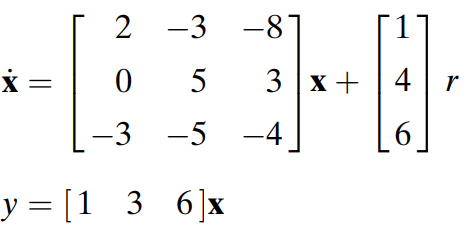

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

You must show all your steps for this question. **If you use built-in Matlab functions such as ss2tf, you will get zero. **

**Answer:**

% Your code goes here
syms s
A = [2, -3, -8; 0, 5, 3; -3, -5, -4];
B = [1;4;6];
C = [1, 3, 6];
D = 0;

X = inv(s*eye(3, 3)-A);
G = simplify(expand(C*X*B+D))

$$G = -\frac{49\,s^{2}-373\,s+680}{-s^{3}+3\,s^{2}+27\,s-103}$$

[n,d] = numden(G);
a = coeffs(d);
RT = [s^3 a(4) a(2); s^2 a(3) a(1)];
RT = [RT;s^1 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) 0];
RT = [RT;s^0 RT(2,3) 0]

$$RT = \left(\begin{array}{ccc} s^{3} & -1 & 27\\ s^{2} & 3 & -103\\ s & -\frac{22}{3} & 0\\ 1 & -103 & 0 \end{array}\right)$$

RT(4,2) = collect(RT(4,2))

$$RT = \left(\begin{array}{ccc} s^{3} & -1 & 27\\ s^{2} & 3 & -103\\ s & -\frac{22}{3} & 0\\ 1 & -103 & 0 \end{array}\right)$$

clear A B C D X G s RT a n d;

**2. Block Diagram (10 marks) (By hand)**

What is the closed loop transfer function $$\frac{Y(s)}{X(s)}$$?

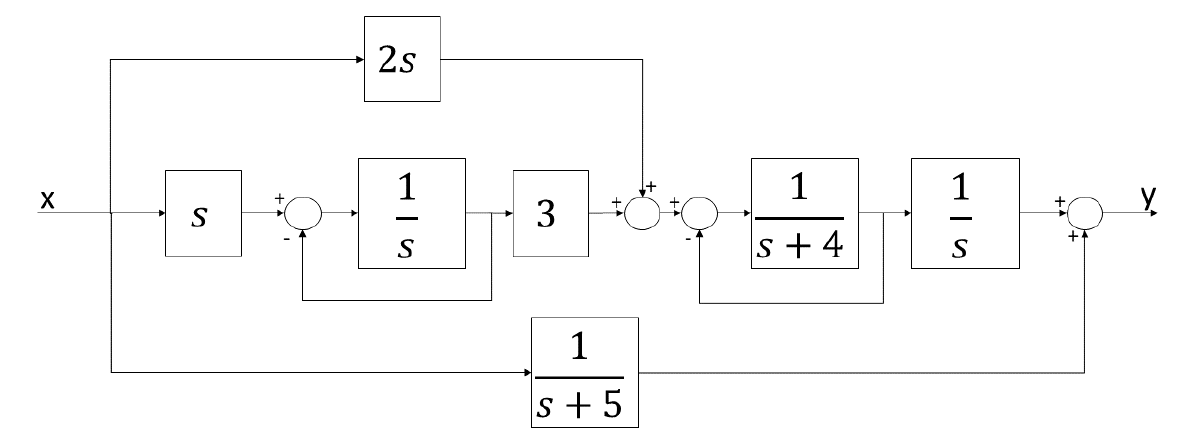

                                                                     **Figure 1: Block Diagram**

DO THIS IN YOUR EXAM BOOKLET. You can do algebraic simplification here but nothing written here will be graded.

**Answer:**

%Your code goes here
syms s
simplify((2*s+3*s/(s+1))/(s*(s+5))+1/(s+5))

$$ans = \frac{3\,\left(s+2\right)}{s^{2}+6\,s+5}$$

factor(s^2+6*s+5, s)

$$ans = \left(\begin{array}{cc} s+5 & s+1 \end{array}\right)$$

**3. Stability and Steady State Error (25 marks) (By hand)**

Consider the following aircraft altitude control system. Here, the altitude is controlled using a proportional controller.

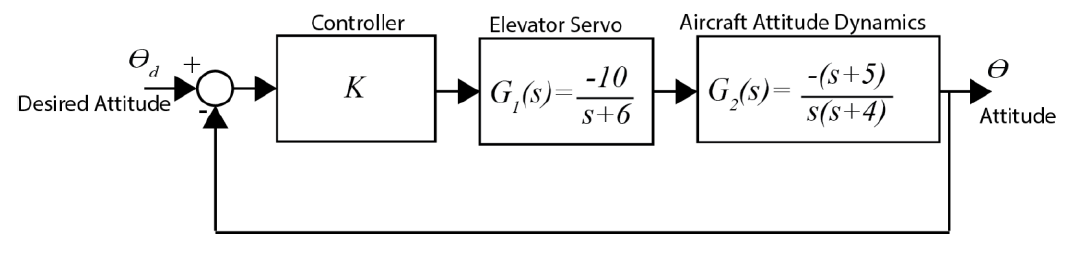

**Figure 2:** Aircraft altitude control system.

a) (10 marks) Determine the range of the controller gain K which results in the closed loop system being stable.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here
syms s k
G_OL = (-10/(s+6))*k*(-(s+5)/(s*(s+4)));
G_CL = simplify(G_OL/(1+G_OL))

$$G\_CL = \frac{10\,k\,\left(s+5\right)}{50\,k+24\,s+10\,k\,s+10\,s^{2}+s^{3}}$$

% G = tf([10*k 20*k], [1 10 (10*k+24) 50*k])
[n,d] = numden(G_CL);
a = coeffs(d, s)

$$a = \left(\begin{array}{cccc} 50\,k & 10\,k+24 & 10 & 1 \end{array}\right)$$

RT = [s^3 a(4) a(2); s^2 a(3) a(1)];
RT = [RT;s^1 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) 0];
RT = [RT;s^0 RT(2,3) 0]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 10\,k+24\\ s^{2} & 10 & 50\,k\\ s & 5\,k+24 & 0\\ 1 & 50\,k & 0 \end{array}\right)$$

simplify(-det([10, 50*k; (50*k+240)/(50*k), 0])/(50*k+240)/(50*k))

$$ans = \frac{1}{50\,k}$$

G =
 
         10 s + 50
  ------------------------
  s^3 + 10 s^2 + 34 s + 50
 
Continuous-time transfer function.



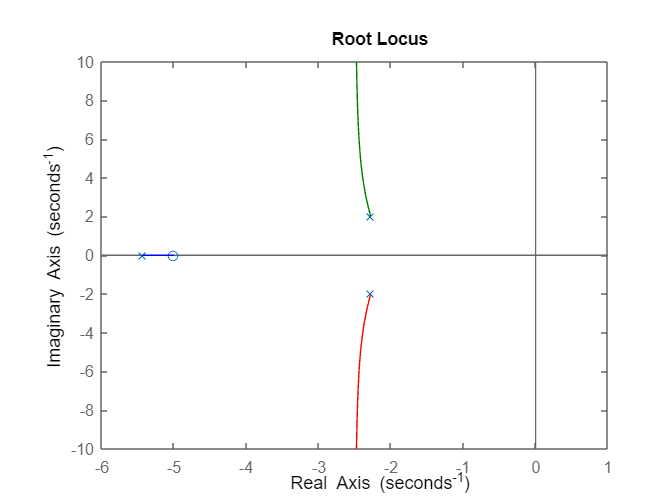

nn = subs(n, k, 1); dd = subs(d, k, 1);
G = tf( sym2poly(nn), sym2poly(dd)), rlocus(G)

b) (5 marks) For a choice of K that stabilizes the system, what would be the steady state error to step input of $$\theta_d(t)=5 u(t)$, $t>=0$$.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here
e_ss = 5/(1+limit(subs(G_CL, k, 1), s, 0))

$$e\_ss = \frac{5}{2}$$

e_ramp = 3/(limit(s*subs(G_CL, k, 1), s, 0))

$$e\_ramp = \infty$$

e_parab = 1/(limit(s^2*subs(G_CL, k, 1), s, 0))

$$e\_parab = \infty$$

c) (5 marks) For a choice of K that stabilizes the system, what would be the steady state error to ramp input of $$\theta_d(t)=3 t u(t)$, $t>=0$$.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here

d) (5 marks) For a choice of K that stabilizes the system, what would be the steady state error to parabolic input of $$\theta_d(t)=t^2 u(t)$, $t>=0$$.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here

**4. Controller Design (30 marks) (In MATLAB)**

We are trying to develop a position controller for a wheeled robot driven by a DC motor. We are measuring the speed using a tachometer and are using feedback to speed up the response and limit system overshoot. The dynamics of the system are shown in the figure below.

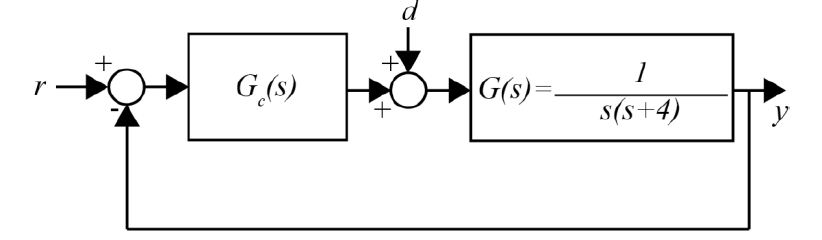

**Figure 4:** Controller Design

(a) (7 marks) First, assuming the disturbance (labelled above as d) is zero, design a proportional controller $$(G_c(s) = K_p)$$ to speed up the response of the system and have a peak time of less than 1 second for a unit step input for the reference.

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

**Answer:**

%Your code goes here
syms s wn zeta K t_p;
G_ol = 1/(s*(s+4));
G_ref = simplify(K*G_ol/(1+K*G_ol))

$$G\_ref = \frac{K}{s^{2}+4\,s+K}$$

k = 20;
G_cl = tf([0 0 k], [1 4 k])

G_cl =
 
        20
  --------------
  s^2 + 4 s + 20
 
Continuous-time transfer function.



peak = max(step(G_cl))

peak = 1.2079

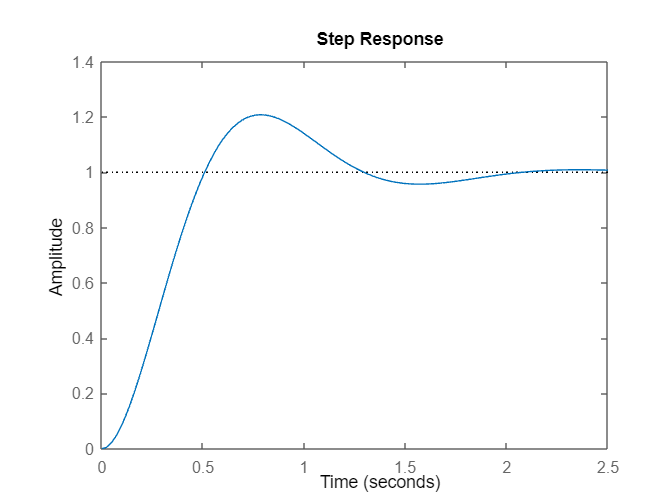

step(G_cl)

%%tp occurs at ~0.78s when k = 20

(b) (4 marks) Also assuming the disturbance (labelled above as d) is zero, design another proportional controller to ensure that the overshoot for a unit step input to the reference remains less than 5%.

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

**Answer:**

%Your code goes here
pos_target = 0.04;

(c) (9 marks) Also assuming the disturbance (labelled above as d) is zero, can you meet both a peak time of less than 1 second and overshoot of less than 5% for a step input to the reference with the same proportional controller? If not, choose another control approach that would speed up the response and limit overshoot. Determine the control gains to meet the requirement.

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

**Answer:**

%Your code goes here

(d) (3 marks) For the controller designed in part c), what would the steady state error be to a unit step input to the reference.

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

**Answer:**

%Your code goes here

(e) (7 marks) For the controller designed in part c), what would the steady-state error be due to a unit step input in the disturbance. If non-zero, suggest what you might add to your controller to get zero steady-state error (no need to design the controller).

DO THIS PROBLEM HERE. Anything in your exam booklet will not be graded. 

**Answer:**

%Your code goes here

**5. Routh-Hurwitz Criterion and Root Locus (25 marks) (By hand)**

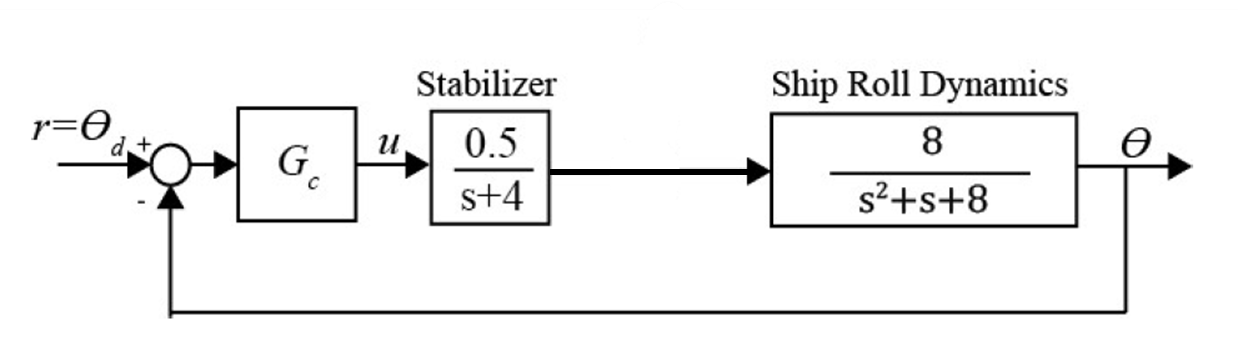

**Figure 4:** Ship Controller.

a) (7 marks) Assume $$G_c(s) = K$$. Determine the transfer function from $$r$$ to $$\theta$$. For what range of $$K$$ is the closed-loop system stable.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here
clear; syms k s;
G_OL=collect(expand(k*0.5/(s+4)*8/(s^2+s+8)))

$$G\_OL = \frac{4\,k}{s^{3}+5\,s^{2}+12\,s+32}$$

G_CL = simplify(G_OL/(1+G_OL))

$$G\_CL = \frac{4\,k}{s^{3}+5\,s^{2}+12\,s+4\,k+32}$$

[n,d] = numden(G_CL);
a = coeffs(d, s);

RT = [s^3 a(4) a(2); s^2 a(3) a(1)];
RT = [RT;s^1 -det([RT(1,2) RT(1,3);RT(2,2) RT(2,3)])/RT(2,2) 0];
RT = [RT;s^0 RT(2,3) 0]

$$RT = \left(\begin{array}{ccc} s^{3} & 1 & 12\\ s^{2} & 5 & 4\,k+32\\ s & \frac{28}{5}-\frac{4\,k}{5} & 0\\ 1 & 4\,k+32 & 0 \end{array}\right)$$

-det([1, 12; 5, 4*k+32])/5

$$ans = \frac{28}{5}-\frac{4\,k}{5}$$

G = simplify(G_OL)

$$G = \frac{4\,k}{s^{3}+5\,s^{2}+12\,s+32}$$

[n, d] = numden(G);
a = double(solve(d == 0, s))

a =   -4.0000 + 0.0000i
  -0.5000 - 2.7839i
  -0.5000 + 2.7839i


syms sigma;
solve([1/(sigma-a(1))+1/(sigma-a(2))+1/(sigma-a(3)) == 0], sigma)

$$ans = \left(\begin{array}{c} -\frac{5}{3}-\frac{\sqrt{11}\,\mathrm{i}}{3}\\ -\frac{5}{3}+\frac{\sqrt{11}\,\mathrm{i}}{3} \end{array}\right)$$

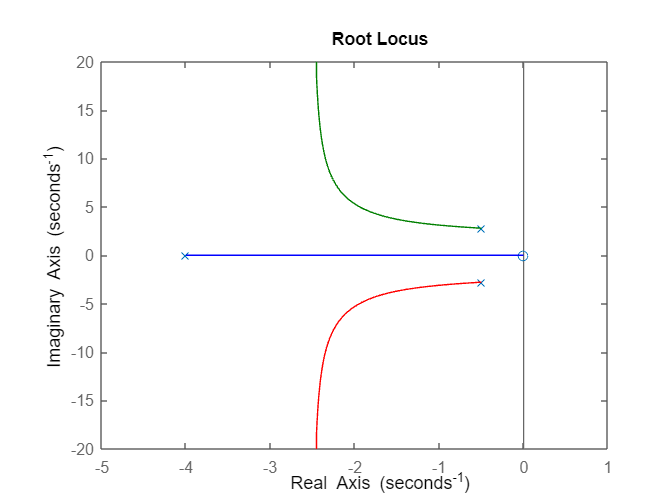

rlocus(tf(sym2poly(n),sym2poly(d)))

b) (8 marks) Sketch the root locus for the system. Be sure to calculate any relevant information such as asymptotes, break-in or breakaway points, departure or arrival angles, and any imaginary-axis crossing points.

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here

c) (10 marks) Design a controller that results in the closed-loop system having an overshoot of 4% or smaller and the system will have a settling time less than 8 seconds. 

DO THIS IN YOUR EXAM BOOKLET. Nothing written in this file will be graded.

You can simplify, plug in your values here and check your answer here.

**Answer:**

%Your code goes here

name="Bartella, Alexander"
studentNumber="400308868"